# Wind Turbine High-Speed Bearing Prognosis

This example shows how to build an **exponential degradation model to predict the Remaining Useful Life** (RUL) of a wind turbine bearing in real time. The exponential degradation model predicts the RUL based on its parameter priors and the latest measurements (historical run-to-failure data can help estimate the model parameters priors, but they are not required). The model is able to detect the significant degradation trend in real time and updates its parameter priors when a new observation becomes available. The example follows a typical **prognosis workflow**: 

- data import and exploration,

- feature extraction and postprocessing, 

- feature importance ranking and fusion, 

- model fitting and prediction, 

- and performance analysis.

## Dataset

### Partial dataset

The dataset is collected from a **[wind turbine specs]** 2MW wind turbine high-speed shaft driven by a 20-tooth pinion gear [1]. A **[data sampling]** vibration signal of 6 seconds was acquired each day for 50 consecutive days (there are 2 measurements on March 17, which are treated as two days in this example). An inner race fault developed and caused the failure of the bearing across the 50-day period. 

A compact version of the dataset is available in the toolbox. To use the compact dataset, copy the dataset to the current folder and enable its write permission.

copyfile(...
    fullfile(matlabroot, 'toolbox', 'predmaint', ...
    'predmaintdemos', 'windTurbineHighSpeedBearingPrognosis'), ...
    'WindTurbineHighSpeedBearingPrognosis-Data-master')
fileattrib(fullfile('WindTurbineHighSpeedBearingPrognosis-Data-master', '*.mat'), '+w')

The measurement time step for the compact dataset is 5 days.

timeUnit = '\times 5 day';

For the full dataset, go to this link [https://github.com/mathworks/WindTurbineHighSpeedBearingPrognosis-Data](https://github.com/mathworks/WindTurbineHighSpeedBearingPrognosis-Data), download the entire repository as a zip file and save it in the same directory as this live script. Unzip the file using this command. The measurement time step for the full dataset is 1 day.

if exist('WindTurbineHighSpeedBearingPrognosis-Data-master.zip', 'file')
    unzip('WindTurbineHighSpeedBearingPrognosis-Data-master.zip')
    timeUnit = 'day';
end

The results in this example are generated from the full dataset. It is highly recommended to download the full dataset to run this example. Results generated from the compact dataset might not be meaningful.

## Data Import

Create a `fileEnsembleDatastore` of the wind turbine data. The data contains a **vibration signal** and a **tachometer signal**. The `fileEnsembleDatastore` will parse the file name and extract the date information as `IndependentVariables`. See the helper functions in the supporting files for more details.

currentfolder = pwd

currentfolder = 'C:\Users\bensi\Documents\Coding\Project\Pole-IA-Predictive-Maintenance\WindTurbine-Prognosis\code\scripts'

hsbearing = fileEnsembleDatastore(...
    fullfile('.', 'WindTurbineHighSpeedBearingPrognosis-Data-master'), ...
    '.mat');
hsbearing.DataVariables = ["vibration", "tach"]

hsbearing =   fileEnsembleDatastore with properties:

                 ReadFcn: []
        WriteToMemberFcn: []
           DataVariables: [2×1 string]
    IndependentVariables: [0×0 string]
      ConditionVariables: [0×0 string]
       SelectedVariables: [0×0 string]
                ReadSize: 1
              NumMembers: 10
          LastMemberRead: [0×0 string]
                   Files: [10×1 string]


hsbearing.IndependentVariables = "Date"

hsbearing =   fileEnsembleDatastore with properties:

                 ReadFcn: []
        WriteToMemberFcn: []
           DataVariables: [2×1 string]
    IndependentVariables: "Date"
      ConditionVariables: [0×0 string]
       SelectedVariables: [0×0 string]
                ReadSize: 1
              NumMembers: 10
          LastMemberRead: [0×0 string]
                   Files: [10×1 string]


hsbearing.SelectedVariables = ["Date", "vibration", "tach"]

hsbearing =   fileEnsembleDatastore with properties:

                 ReadFcn: []
        WriteToMemberFcn: []
           DataVariables: [2×1 string]
    IndependentVariables: "Date"
      ConditionVariables: [0×0 string]
       SelectedVariables: [3×1 string]
                ReadSize: 1
              NumMembers: 10
          LastMemberRead: [0×0 string]
                   Files: [10×1 string]


hsbearing.ReadFcn = @helperReadData;
hsbearing.WriteToMemberFcn = @helperWriteToHSBearing;
tall(hsbearing)

ans =

  M×3 tall table

            Date                vibration             tach     
    ____________________    _________________    ______________

    11-Mar-2013 03:00:24    {292968×1 double}    {187×1 double}
    16-Mar-2013 06:56:43    {292968×1 double}    {180×1 double}
    21-Mar-2013 00:33:14    {292968×1 double}    {188×1 double}
    26-Mar-2013 01:41:50    {292968×1 double}    {180×1 double}
    31-Mar-2013 19:38:18    {292968×1 double}    {180×1 double}
    05-Apr-2013 21:35:37    {292968×1 double}    {182×1 double}
    10-Apr-2013 23:14:07    {292968×1 double}    {187×1 double}
    15-Apr-2013 22:55:24    {292968×1 double}    {167×1 double}
             :                      :                  :
             :                      :               

Sample rate of vibration signal is 97656 Hz. 

fs = 97656; % Hz

## Data Exploration

This section explores the data in both time domain and frequency domain and seeks inspiration of what features to extract for prognosis purposes.

First visualize the vibration signals in the time domain. In this dataset, there are 50 vibration signals of 6 seconds measured in 50 consecutive days. Now plot the 50 vibration signals one after each other.

reset(hsbearing)
tstart = 0;
figure
hold on
currentfolder = pwd

currentfolder = 'C:\Users\bensi\Documents\Coding\Project\Pole-IA-Predictive-Maintenance\WindTurbine-Prognosis\code\scripts'

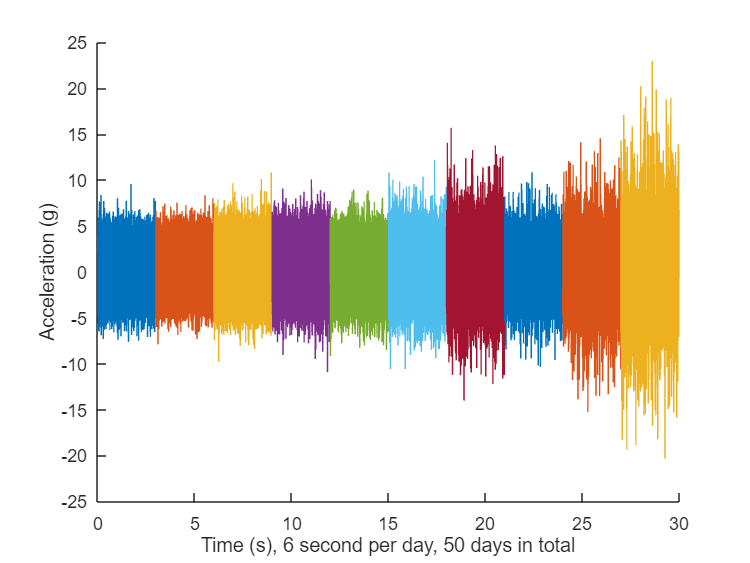

while hasdata(hsbearing)
    data = read(hsbearing);
    v = data.vibration{1};
    t = tstart + (1:length(v))/fs;
    % Downsample the signal to reduce memory usage
    plot(t(1:10:end), v(1:10:end))
    tstart = t(end);
end
hold off
xlabel('Time (s), 6 second per day, 50 days in total')
ylabel('Acceleration (g)')

The vibration signals in time domain reveals an increasing trend of the signal impulsiveness. Indicators quantifying the impulsiveness of the signal, such as kurtosis, peak-to-peak value, crest factors *etc.*, are potential prognostic features for this wind turbine bearing dataset [2]. 

On the other hand, spectral kurtosis is considered powerful tool for wind turbine prognosis in frequency domain [3]. To visualize the spectral kurtosis changes along time, plot the spectral kurtosis values as a function of frequency and the measurement day.

hsbearing.DataVariables = ["vibration", "tach", "SpectralKurtosis"];
colors = parula(50);
figure
hold on
reset(hsbearing)
day = 1;
currentfolder = pwd

currentfolder = 'C:\Users\bensi\Documents\Coding\Project\Pole-IA-Predictive-Maintenance\WindTurbine-Prognosis\code\scripts'

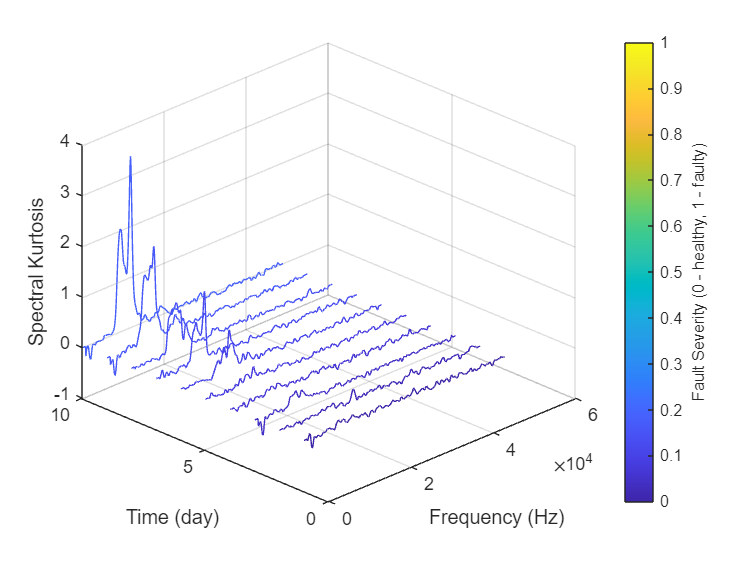

while hasdata(hsbearing)
    data = read(hsbearing);
    data2add = table;
    
    % Get vibration signal and measurement date
    v = data.vibration{1};
    
    % Compute spectral kurtosis with window size = 128
    wc = 128;
    [SK, F] = pkurtosis(v, fs, wc);
    data2add.SpectralKurtosis = {table(F, SK)};
    
    % Plot the spectral kurtosis
    plot3(F, day*ones(size(F)), SK, 'Color', colors(day, :))
    
    % Write spectral kurtosis values
    writeToLastMemberRead(hsbearing, data2add);
    
    % Increment the number of days
    day = day + 1;
end
hold off
xlabel('Frequency (Hz)')
ylabel('Time (day)')
zlabel('Spectral Kurtosis')
grid on
view(-45, 30)
cbar = colorbar;
ylabel(cbar, 'Fault Severity (0 - healthy, 1 - faulty)')

Fault Severity indicated in colorbar is the measurement date normalized into 0 to 1 scale. It is observed that the spectral kurtosis value around 10 kHz gradually increases as the machine condition degrades. Statistical features of the spectral kurtosis, such as mean, standard deviation *etc.*, will be potential indicators of the bearing degradation [3].

## References

[1] Bechhoefer, Eric, Brandon Van Hecke, and David He. "Processing for improved spectral analysis." *Annual Conference of the Prognostics and Health Management Society, New Orleans, LA, Oct*. 2013.

[2] Ali, Jaouher Ben, et al. "Online automatic diagnosis of wind turbine bearings progressive degradations under real experimental conditions based on unsupervised machine learning." *Applied Acoustics* 132 (2018): 167-181.

[3] Saidi, Lotfi, et al. "Wind turbine high-speed shaft bearings health prognosis through a spectral Kurtosis-derived indices and SVR." *Applied Acoustics* 120 (2017): 1-8.

*Copyright 2022 The MathWorks, Inc.*